# Parameter Estimation for Discrete-SIR models

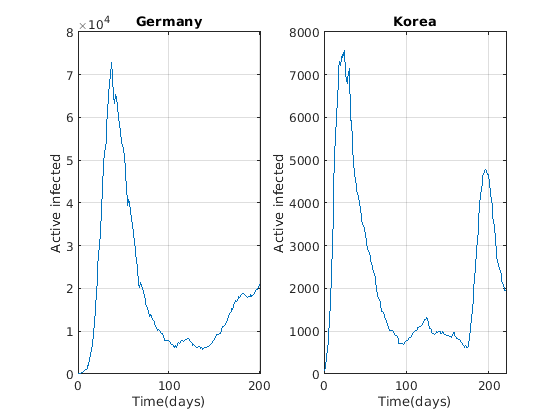

Localities = ["Germany", "Korea"];

time = {40:240; 30:250};
Population = [8.3e7; 5.1e7];
ydata = cell(length(Localities),1);

for i = 1: length(Localities)
    load('../Data/' + Localities(i) + '.mat')
    ydata_aux = [Cases - Recovered - Death; Recovered];
    ydata{i} = ydata_aux(:,time{i});
end

figure
subplot(1,2,1)
plot(ydata{1}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{1})

subplot(1,2,2)
plot(ydata{2}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{2})

Parameter estimation model simple, complex and classic probabilities  

VarNames = {'N','I_f','I_q','I_j','R','R_j'};
OutNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j','N','\aleph', 'G(t)', 'Cum(I_q)'};
ParNames = {'a','\lambda','\alpha','\mu', '\theta', '\gamma', '\nu', 'z', '\beta'};

FullNames = [VarNames, ParNames];

ModelNames = ["Simple", "Complex", "Classic"];

T_save = cell(length(Localities), length(ModelNames));  

ModelfncName = "CHIMERA_FQ";
% ModelfncName = "CHIMERA_FQ_equilibrio";

for k = 1:length(Localities)
% for k=2:2
    RealData = ydata{k};    
    
    Range1 = [
        Population(k) Population(k);    %N
        0 1000;                         %I_f                
        0 0;                            %I_q
        RealData(1,1) RealData(1,1);    %I_j
        RealData(2,1) RealData(2,1);    %R_total
        RealData(2,1) RealData(2,1);    %R_j
        ];
    
    Range2 = [
                0 1;        %a    
                0 1;        %lambda 
                0 1;        %alpha
                0 0;        %mu 
                0 1;        %theta
                0 1;        %gamma 
                0 1000;     %nu 
                0 300;       %z 
                0 1         %beta 
    ];
    
    RangeT = [Range1; Range2];
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    N = 100;
    extra = struct();
    Parameters = [];
    Res = [];
     
    for i = 1:3
%     for i = 2:2    
        extra.Prob = i;
        %%Prob = 1 -> psi(simple)
        %%Prob = 2 -> phi(complex)
        %%Prob = 3 -> classical
        
        [T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);
        outs = [5]; 
        T.Properties.CustomProperties.output = outs;
        
        if i == 3
            %z
            T.Range(end-1,:) = [0 0];
            T.Nominal(end-1) = 0;
            %beta
            T.Range(end,:) = [0 1];
            T.Nominal(end) = 0.5;
        end
        
        if i == 2
            %nu
            T.Range(end-2,:) = [0 30000];
        end
        
        T_save{k, i} = T;
        
        Solver = 'fmincon';
           
        Opt = optimoptions('fmincon', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
            'MaxIterations', 3000, 'Display','off');
        
        parfor j = 1:N
    %     for j = 1:N
            [T_aux, Res_aux] = gsua_pe(T, xdata, RealData(1,:),...
                'solver', Solver,'N', 1,'opt', Opt,'save', false);
            Parameters(:,j) = T_aux.Estfmincon;
            Res(j) = Res_aux;
        end
        
        [Res, idx] = sort(Res);
        Parameters = Parameters(:,idx);     
        T_save{i}.Nominal = Parameters(:,1);
        save("Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i), "Res",  "Parameters")
        
        figure
        gsua_eval(Parameters(:,1), T_save{k, i}, xdata, RealData(1,:));
        suptitle(ModelNames(i) + " residual: " + Res(1) + " Locality:" + Localities{k})
    end
end

Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function


[T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);

Setting environment to work with user-defined function


outs = [5]; 
T.Properties.CustomProperties.output = outs;
T_aux = [];
for k = 1:length(Localities)
%     Localities(k)
    for i = 1:3
    load("ResultsCovid/Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i))
    T_aux = [T_aux, Parameters(:,1)];
%     ModelNames(i)
    end
end
T.Params = T_aux;
T

T = 9×3 table
                 Range      Nominal       Params   
               _________    _______    ____________

    I_f        0    1000      500      [1×6 double]
    a          0       1      0.5      [1×6 double]
    \lambda    0       1      0.5      [1×6 double]
    \alpha     0       1      0.5      [1×6 double]
    \theta     0       1      0.5      [1×6 double]
    \gamma     0       1      0.5      [1×6 double]
    \nu        0    1000      500      [1×6 double]
    z          0      30       15      [1×6 double]
    \beta      0       1      0.5      [1×6 double]


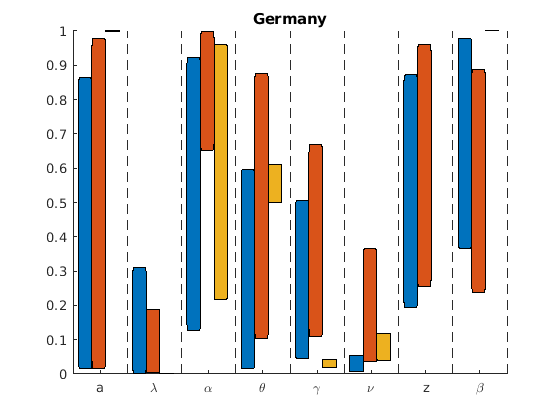

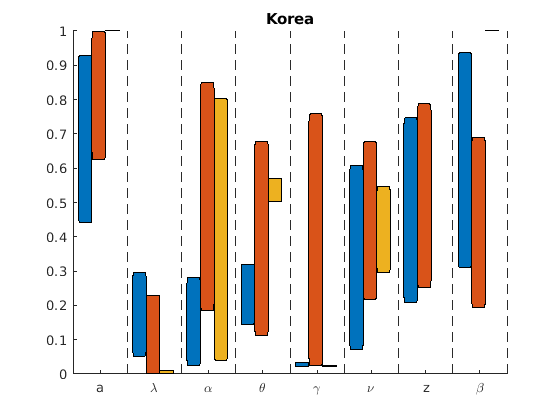

close all
for k = 1 :2
figure
FolderFigures = "/MATLAB Drive/CHIMERITApaper/Figures/";
A = rand(3,3);
cm = colormap(lines(size(A,1)));
x=[];
mx=[];
P=[];

for i=1:3
    load("ResultsCovid/Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i))
    P = (Parameters-T_save{k, i}.Range(:,1))./(T_save{k, i}.Range(:,2)-T_save{k, i}.Range(:,1));
    
    for j = 1:9
        if i ~= 3 || j ~= 8 
            Pq = rmoutliers(P(j,:),'percentiles', [10 90]);
            Pq = quantile(Pq',[0.25 0.75])';
    %         Pq = [min(Pq) max(Pq)]';
            rectangle('Position',[j+0.25*(i-1) Pq(1) 1/4 Pq(2)-Pq(1)],'FaceColor',[cm(i,:),0.5],'Curvature',0.2)
            hold on
    %         text(0,j+0.75,string(T_save{k, i}.Properties.RowNames(j)))

        end
            x(j) = j+0.9;
            xline(x(j),'--')
            if j>1
                mx(j) = x(j-1)+(x(j)-x(j-1))/2;
            else
                mx(j) = (x(j)+1)/2;
            end          
    end
end

    xlim([min(x) max(x)])
    xticks(mx)
    set(gca,'XTickLabel',T_save{k, i}.Properties.RowNames,'TickLabelInterpreter', 'tex')
    title(Localities(k))    
%     savefig(FolderFigures + "PIA_" + Localities(k) + "_Discrete.fig")
%     saveas(gcf,FolderFigures + "PIA_" + Localities(k) + "_Discrete.png")
end

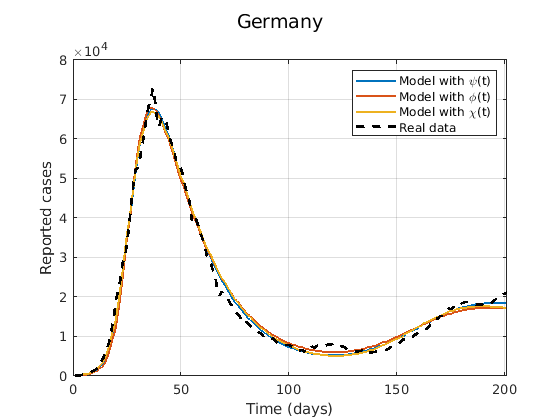

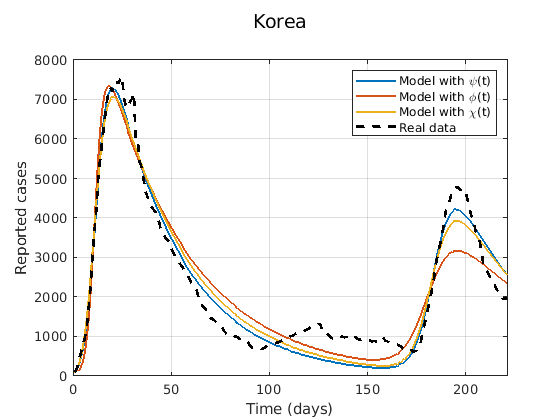

close all
IdxSims = [];

FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/";

Titles = ["Model with \psi(t)"; 
    "Model with \phi(t)";
    "Model with \chi(t)";
    "Real data"];

for k = 1:length(Localities)
    
    A = rand(3,3);
    cm = colormap(lines(size(A,1)));
    
    counter = 1;
    RealData = ydata{k};    
    figure
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    for i = 1:3
%         load("ResultsCovid/Estimations_Disc_2_" + Localities(k) + "_Aleph_" + ModelNames(i))
        load("ResultsCovid/Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        T_save{k,i}.Properties.CustomProperties.output = 5;
        ysim = zeros(N, 1, D);
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
%             subplot(3,1,counter)
            plot(squeeze(ysim(IdxSims(k), j, :))', 'Color', cm(i,:),'LineWidth',1.5); 
            hold on
            grid on
%             title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
        suptitle(Localities(k))
    end
    xlabel("Time (days)")
    ylabel("Reported cases")
    hold on
    plot(RealData(j,:)','--k','LineWidth',2)
    legend(Titles)    
%     savefig(FolderFigures + "Fit_" + Localities(k) + "Discrete.fig")
%     saveas(gcf,FolderFigures + "Fit_" + Localities(k) + "Discrete.png")
end

## Probabilities vs time

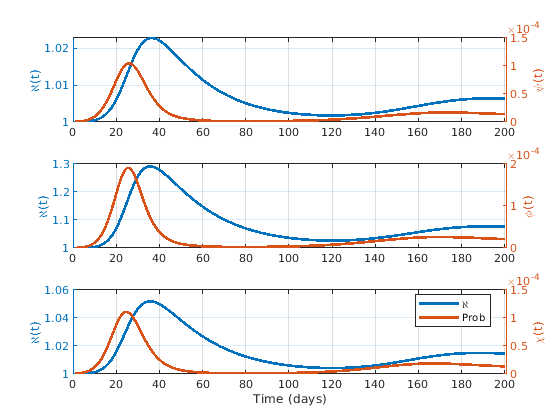

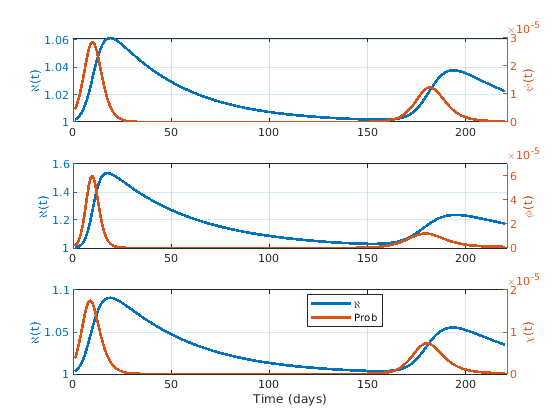

IdxSims = [];
Titles = ["Infected with \psi(t)"; 
    "Infected with \phi(t)";
    "Infected with classic"];
Prob = ["\psi(t)", "\phi(t)", "\chi(t)"];
for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure
    for i = 1:3
%         load("ResultsCovid/Estimations_Disc_2_" + Localities(k) + "_Aleph_" + ModelNames(i))
        load("ResultsCovid/Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        ysim = zeros(N, 2, D);
        T_save{k,i}.Properties.CustomProperties.output = [9,10];
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
            subplot(3,1,counter)
            yyaxis left
            plot(squeeze(ysim(IdxSims(k), j, 2:end))', 'LineWidth',2); 
            ylabel("\aleph(t)")            
           hold on
            yyaxis right
            plot(squeeze(ysim(IdxSims(k), j+1, 2:end))', 'LineWidth',2); 
            ylabel(Prob(counter))
            grid on
%             title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
%         suptitle(Localities(k))
    end
    legend("\aleph","Prob",'location','best')
    xlabel("Time (days)")    
%     savefig(FolderFigures + "Probs_" + Localities(k) + "Discrete.fig")
%     saveas(gcf,FolderFigures + "Probs_" + Localities(k) + "Discrete.png")
end

## All states

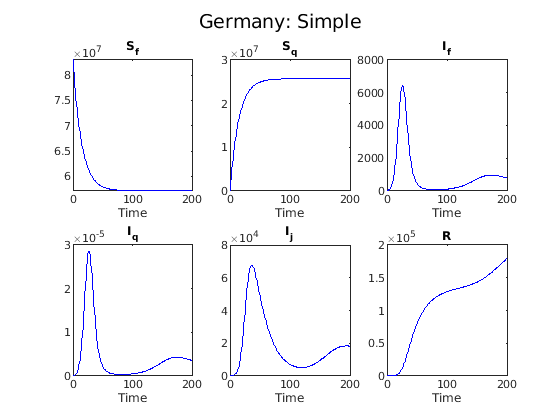

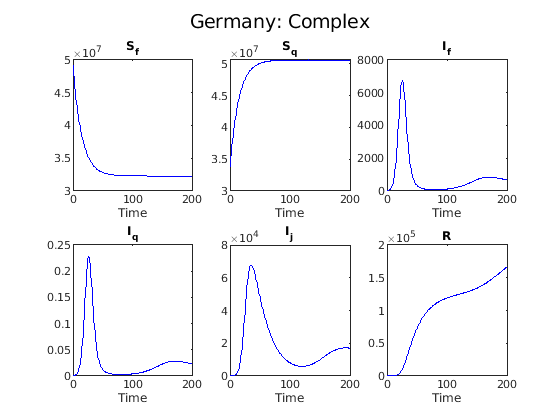

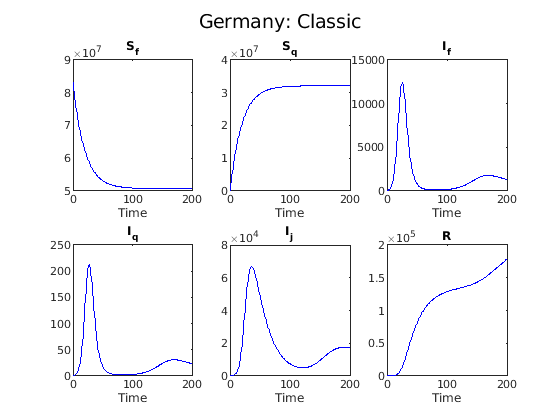

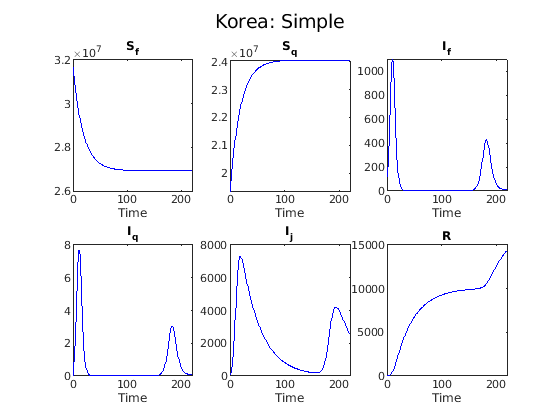

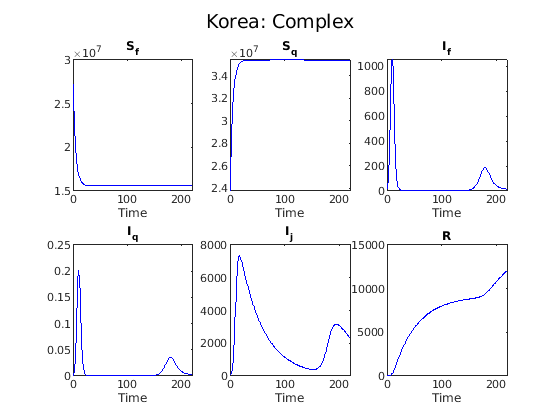

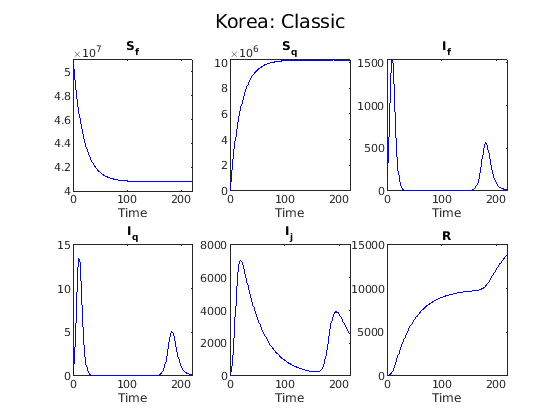

for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure
    for i = 1:3
        load("ResultsCovid/Estimations_Disc_a_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        ysim = zeros(N, 2, D);
        T_save{k,i}.Properties.CustomProperties.output = 1:6;
        figure
        gsua_eval(Parameters(:,1), T_save{k,i}, xdata);
        suptitle(Localities(k) + ": " + ModelNames(i))
    end 
end

**Sensitivity analisys for estimation intervals for I_j**

indexSA = [];
N = 500000;
SUM = zeros(3,1);
for i = 1:3
    T_save{2,i}.Properties.CustomProperties.output = 5;
    
    if i == 3
        T_save{2,i}.Nominal(end) = 0.5;
    end
    M = gsua_dmatrix(T_save{2,i}, N, 'Method', 'Sobol');
    T_SA{i} = gsua_sa(M,T_save{2,i});    
    SUM(i) = sum(T_SA{i}.Si)/sum(abs(T_SA{i}.Si));
    indexSA = [indexSA, T_SA{i}.STi];
end
SUM
save("T_SA_Ij", "T_SA")

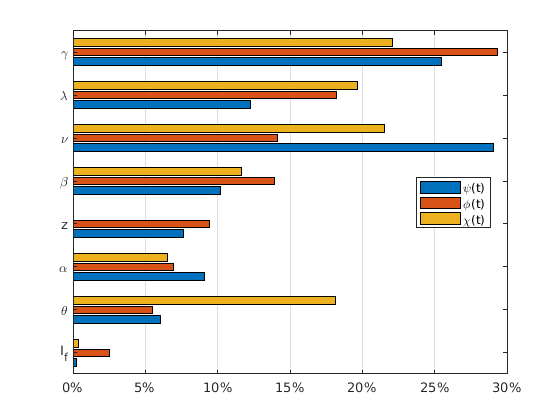

figure
indexSA2 = indexSA*100./(sum(indexSA));
[~, ixd] = sort(indexSA2(:,2));
% X = categorical(T.Properties.RowNames(ixd));
barh(indexSA2(ixd,:))
yticklabels(T.Properties.RowNames(ixd))
legend({"\psi(t)", "\phi(t)", "\chi(t)"}, 'location', 'best')
ax = gca;
ax.XGrid = 'on';
xtickformat('percentage')

ax.YGrid = 'off';
% savefig(FolderFigures + "SA_Ij_Bar_Discrete.fig")
% saveas(gcf,FolderFigures + "SA_Ij_Bar_Discrete.png")